clear all;
human_dist = load('Humans/AreaDistances.mat');
human_size = load('allhumandata.mat');human_size = human_size.humandata;

monks=load('Monks/alldata.mat');
monks_dist=load('Monks/intermediate_files');

% Human Data
disp(human_dist.area_labels)

  Columns 1 through 13

    {'V1all'}    {'V1v'}    {'V1d'}    {'V2v'}    {'V2d'}    {'V3v'}    {'V3d'}    {'V3A'}    {'V3B'}    {'LO1'}    {'LO2'}    {'TO1'}    {'TO2'}

  Columns 14 through 25

    {'hV4'}    {'VO1'}    {'VO2'}    {'PHC1'}    {'PHC2'}    {'IPS0'}    {'IPS1'}    {'IPS2'}    {'IPS3'}    {'IPS4'}    {'IPS5'}    {'SPL1'}

  Columns 26 through 27

    {'FEF'}    {'IFS'}



dist_to_data_idx = [2,3,4,5,6,7,14,15,16,17,18,8,9,10,11,12,13,19,20,21,22,23,24,25];
from_v1_idx = find(human_dist.alluniqueroinodepairs(:,1)==0);
distance_from_v1_rh = human_dist.allareadistancesavglayer_rh(from_v1_idx,:);
distance_from_v1_lh = human_dist.allareadistancesavglayer_lh(from_v1_idx,:);
dist_from_v1_rh = distance_from_v1_rh(dist_to_data_idx-1,:);
dist_from_v1_lh = distance_from_v1_lh(dist_to_data_idx-1,:);
human_labels_vd = human_dist.area_labels(dist_to_data_idx);

meanhumans_cortdist_rh = mean(dist_from_v1_rh,2,'omitnan');
meanhumans_cortdist_lh = mean(dist_from_v1_lh,2,'omitnan');

meanhumans_cortdist_rh1234=[];
meanhumans_cortdist_rh1234(1)=0;
meanhumans_cortdist_rh1234(2)=[meanhumans_cortdist_rh(3)+meanhumans_cortdist_rh(4)]/2;
meanhumans_cortdist_rh1234(3)=[meanhumans_cortdist_rh(5)+meanhumans_cortdist_rh(6)]/2;
meanhumans_cortdist_rh1234=[meanhumans_cortdist_rh1234,meanhumans_cortdist_rh(7:end)'];

meanhumans_cortdist_lh1234=[];
meanhumans_cortdist_lh1234(1)=0;
meanhumans_cortdist_lh1234(2)=[meanhumans_cortdist_lh(3)+meanhumans_cortdist_lh(4)]/2;
meanhumans_cortdist_lh1234(3)=[meanhumans_cortdist_lh(5)+meanhumans_cortdist_lh(6)]/2;
meanhumans_cortdist_lh1234=[meanhumans_cortdist_lh1234,meanhumans_cortdist_lh(7:end)'];

meanhumans_cortdist1234=[meanhumans_cortdist_lh1234+meanhumans_cortdist_lh1234]/2;

% Monkey Data
meanmonks_cortdist_rh=nanmean(monks_dist.avgdist_allsubjs_rh,2);
meanmonks_cortdist_lh=nanmean(monks_dist.avgdist_allsubjs_lh,2);

meanmonks_cortdist_rh1234=[];
meanmonks_cortdist_rh1234(1)=[meanmonks_cortdist_rh(1)+meanmonks_cortdist_rh(2)];
meanmonks_cortdist_rh1234(2)=[meanmonks_cortdist_rh(3)+meanmonks_cortdist_rh(4)]/2;
meanmonks_cortdist_rh1234(3)=[meanmonks_cortdist_rh(5)+meanmonks_cortdist_rh(6)]/2;
meanmonks_cortdist_rh1234(4)=[meanmonks_cortdist_rh(7)+meanmonks_cortdist_rh(8)]/2;
meanmonks_cortdist_rh1234(5)=[meanmonks_cortdist_rh(9)+meanmonks_cortdist_rh(10)]/2;
meanmonks_cortdist_rh1234=[meanmonks_cortdist_rh1234,meanmonks_cortdist_rh(11:end)'];

meanmonks_cortdist_lh1234=[];
meanmonks_cortdist_lh1234(1)=[meanmonks_cortdist_lh(1)+meanmonks_cortdist_lh(2)];
meanmonks_cortdist_lh1234(2)=[meanmonks_cortdist_lh(3)+meanmonks_cortdist_lh(4)]/2;
meanmonks_cortdist_lh1234(3)=[meanmonks_cortdist_lh(5)+meanmonks_cortdist_lh(6)]/2;
meanmonks_cortdist_lh1234(4)=[meanmonks_cortdist_lh(7)+meanmonks_cortdist_lh(8)]/2;
meanmonks_cortdist_lh1234(5)=[meanmonks_cortdist_lh(9)+meanmonks_cortdist_lh(10)]/2;
meanmonks_cortdist_lh1234=[meanmonks_cortdist_lh1234,meanmonks_cortdist_lh(11:end)'];

meanmonks_cortdist1234=[meanmonks_cortdist_lh1234+meanmonks_cortdist_lh1234]/2;

% Human Labels
human_labels =           [{'V1', 'V2', 'V3'},human_labels_vd{7:end}];
disp(human_labels)

  Columns 1 through 13

    {'V1'}    {'V2'}    {'V3'}    {'hV4'}    {'VO1'}    {'VO2'}    {'PHC1'}    {'PHC2'}    {'V3A'}    {'V3B'}    {'LO1'}    {'LO2'}    {'TO1'}

  Columns 14 through 21

    {'TO2'}    {'IPS0'}    {'IPS1'}    {'IPS2'}    {'IPS3'}    {'IPS4'}    {'IPS5'}    {'SPL1'}



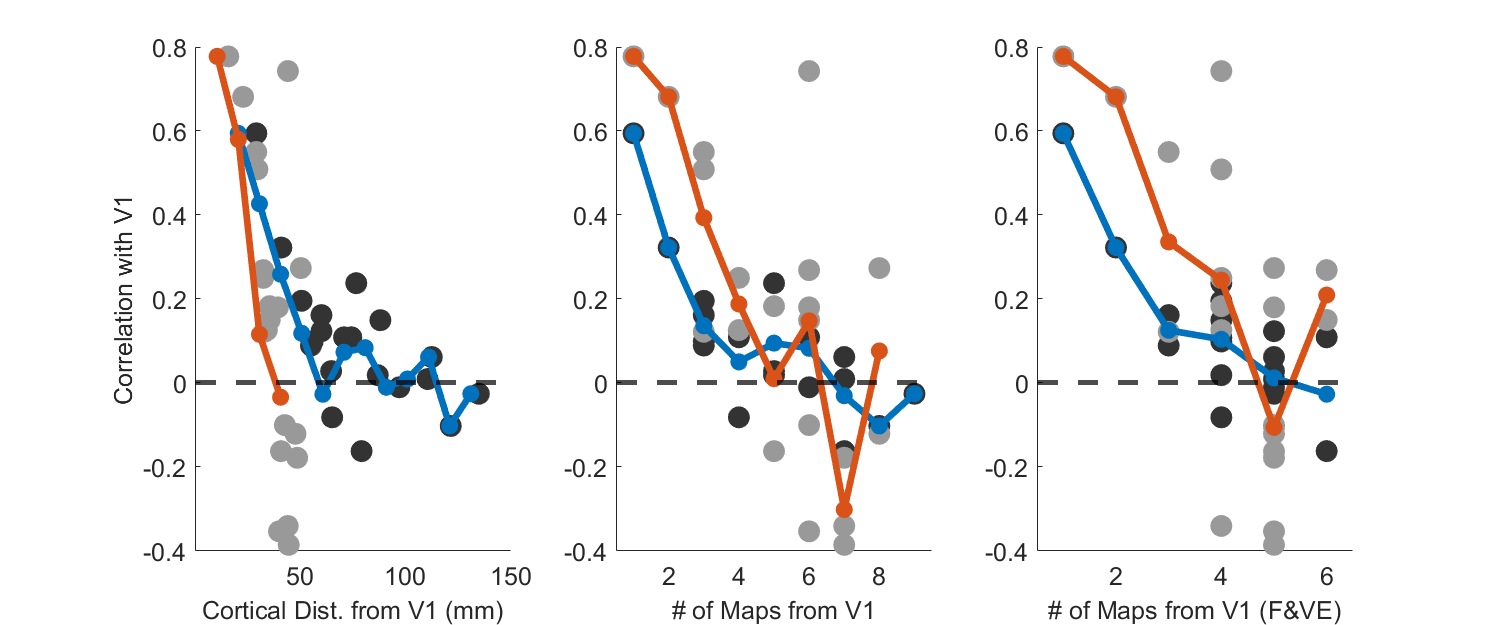

human_areadistfromV1 =   [ 0, 1, 2, 3, 4, 5, 6, 7, 3, 3, 3, 4, 5, 6, 4, 5, 6, 7, 8, 9, 7];
human_fellemanhierarchy = [1, 2, 3, 5, 6, 6, 7, 7, 4, 4, 5, 5, 5, 5, 5, 5, 6, 6, 6, 6, 6]-1;

% Monkey Labels
monk_labels =           {'V1', 'V2', 'V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','CIP1','CIP2','LIP1','LIP2','LIP3','MT','MST','FST','V4t'};
monk_areadistfromV1=      [0,    1,    2,   3,   4,   5,     6,    6,      6,      6,    3,    3,    4,    5,     6,     7,     8,     6,   7,    8,   7];
monk_fellemanhierarchy=   [1,    2,    3,   5,   5,   6,     6,    6,      7,      7,    4,    4,    5,     5,    6,     6,     6,     5,   6,    6,   5]-1;

monks_allareas=monks.V1_cat_corr1234;

% Human Analysis from Separate Data
% calculate sum of retinal (removing v7), parietal, and frontal areas
for i = 1:2
    surfacearea_smoothwm{i} = [human_size.retino_surfacearea_smoothwm{i}([1:13,15:18],:);human_size.parietal_surfacearea_smoothwm{i}];
    surfacearea_pial{i} = [human_size.retino_surfacearea_pial{i}([1:13,15:18],:);human_size.parietal_surfacearea_pial{i}];
end

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
human_surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);
human_bothhemi_SA = [human_surfacearea_avg{1}, human_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = human_bothhemi_SA(1,:) + human_bothhemi_SA(2,:);
V2_sumhemis_sumvd = sum(human_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(human_bothhemi_SA(5:6,:),1);
V4_sumhemis_sumvd = human_bothhemi_SA(7,:);

SA_sumvd_human = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;V4_sumhemis_sumvd;human_bothhemi_SA(8:end,:)];


monks_avg_lh = (monks.retino_surfacearea_pial_lh + monks.retino_surfacearea_smoothwm_lh)/2;
monks_avg_lh(:,5) = [];
monks_avg_rh = (monks.retino_surfacearea_pial_rh + monks.retino_surfacearea_smoothwm_rh)/2;
monks_avg_rh(:,5) = [];
monks_bothhemis = [monks_avg_rh, monks_avg_lh];

% restructure summed hemisphere data to get area categories we want to display
V1_bothhemis_sumvd = sum(monks_bothhemis(1:2,:),1);
V2_bothhemis_sumvd = sum(monks_bothhemis(3:4,:),1);
V3_bothhemis_sumvd = sum(monks_bothhemis(5:6,:),1);
V4_bothhemis_sumvd = sum(monks_bothhemis(7:8,:),1);
V4A_bothhemis_sumvd = sum(monks_bothhemis(9:10,:),1);

SA_sumvd_monkey = [V1_bothhemis_sumvd;V2_bothhemis_sumvd;...
    V3_bothhemis_sumvd;V4_bothhemis_sumvd;V4A_bothhemis_sumvd;monks_bothhemis(11:end,:)];

human_v1_corr = zeros(1,size(SA_sumvd_human,1));
monkey_v1_corr = zeros(1,size(SA_sumvd_monkey,1));
for ii = 1:size(SA_sumvd_human,1)
    exclude_nan = find(~isnan(SA_sumvd_human(ii,:)));
    SA_area = SA_sumvd_human(ii,exclude_nan);
    SA_v1 = SA_sumvd_human(1,exclude_nan);
    human_v1_corr(ii) = corr2(SA_area,SA_v1);
    
    exclude_nan = find(~isnan(SA_sumvd_monkey(ii,:)));
    SA_area = SA_sumvd_monkey(ii,exclude_nan);
    SA_v1 = SA_sumvd_monkey(1,exclude_nan);
    monkey_v1_corr(ii) = corr2(SA_area,SA_v1);
end

% Calculate average correlation with v1 across subjects
for x = 1:max([monk_areadistfromV1,human_areadistfromV1])
    human_meanareadist(x)=nanmean(human_v1_corr(human_areadistfromV1==x));
    monk_meanareadist(x)=nanmean(monkey_v1_corr(monk_areadistfromV1==x));
end

for x = 1:max([monk_fellemanhierarchy,human_fellemanhierarchy])
    human_meanhierarchydist(x)=nanmean(human_v1_corr(human_fellemanhierarchy==x)); 
    monk_meanhierarchydist(x)=nanmean(monkey_v1_corr(monk_fellemanhierarchy==x));
end

stepsize=10;
maxrange=150;
human_meancortdist=nan(length(1:stepsize:maxrange),1);
monk_meancortdist=nan(length(1:stepsize:maxrange),1);
count = 0;
for x = 1:stepsize:maxrange
    count = count+1;
    if x < 150
        if sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]) > 1
            monk_meancortdist(count)=nanmean(monkey_v1_corr([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<x+stepsize]));
        elseif sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)])
            monk_meancortdist(count)=monkey_v1_corr([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]);
        end
        if sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]) > 1
            human_meancortdist(count)=nanmean(human_v1_corr([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]));
        elseif sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)])
            human_meancortdist(count)=human_v1_corr([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]);
        end
    end
end
human_meancortdist(4)=[human_meancortdist(3)+human_meancortdist(5)]/2;
% human_meancortdist(7)=[human_meancortdist(6)+human_meancortdist(8)]/2;
% human_meancortdist(14)=[human_meancortdist(13)+human_meancortdist(15)]/2;

figure('Renderer', 'painters', 'Position', [10 10 1200 500])
subplot(1,3,1) 
hold on
plot(meanhumans_cortdist1234(2:end),human_v1_corr(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(meanmonks_cortdist1234(2:end),monkey_v1_corr(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(1:stepsize:maxrange,human_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(1:stepsize:maxrange,monk_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
yline(0,'k--','LineWidth',3)
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 150])
xlabel('Cortical Dist. from V1 (mm)','fontsize',15)
ylabel('Correlation with V1','fontsize',15)

subplot(1,3,2)
hold on
plot(human_areadistfromV1(2:end),human_v1_corr(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(monk_areadistfromV1(2:end),monkey_v1_corr(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(human_meanareadist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(monk_meanareadist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
yline(0,'k--','LineWidth',3)
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([monk_areadistfromV1,human_areadistfromV1])+.5])
xlabel('# of Maps from V1','Fontsize',15)
 
subplot(1,3,3)
hold on
plot(human_fellemanhierarchy(2:end),human_v1_corr(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(monk_fellemanhierarchy(2:end),monkey_v1_corr(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(human_meanhierarchydist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(monk_meanhierarchydist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
yline(0,'k--','LineWidth',3)
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([monk_fellemanhierarchy,human_fellemanhierarchy])+.5])
xlabel('# of Maps from V1 (F&VE)','Fontsize',15)

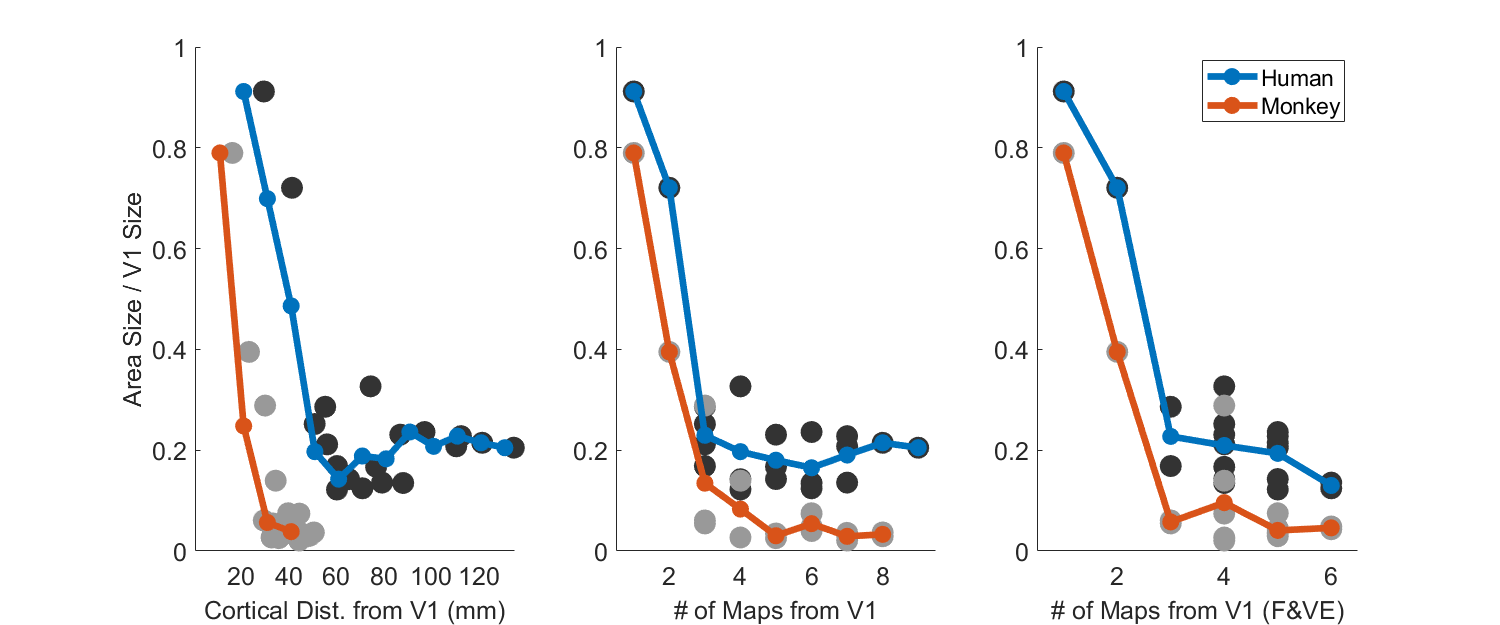

human_bothhemi_SA = [human_surfacearea_avg{1}, human_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(human_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(human_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(human_bothhemi_SA(5:6,:),1);

SA_sumvd_human = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;human_bothhemi_SA(7:end,:)];

humans_allareas = SA_sumvd_human./SA_sumvd_human(1,:);
humans_allareas = mean(humans_allareas,2,'omitnan');

monks_avg_lh = (monks.retino_surfacearea_pial_lh + monks.retino_surfacearea_smoothwm_lh)/2;
monks_avg_rh = (monks.retino_surfacearea_pial_rh + monks.retino_surfacearea_smoothwm_rh)/2;
monks_bothhemis = [monks_avg_rh, monks_avg_lh];

% restructure summed hemisphere data to get area categories we want to display
V1_bothhemis_sumvd = sum(monks_bothhemis(1:2,:),1);
V2_bothhemis_sumvd = sum(monks_bothhemis(3:4,:),1);
V3_bothhemis_sumvd = sum(monks_bothhemis(5:6,:),1);
V4_bothhemis_sumvd = sum(monks_bothhemis(7:8,:),1);
V4A_bothhemis_sumvd = sum(monks_bothhemis(9:10,:),1);

SA_sumvd_monkey = [V1_bothhemis_sumvd;V2_bothhemis_sumvd;...
    V3_bothhemis_sumvd;V4_bothhemis_sumvd;V4A_bothhemis_sumvd;monks_bothhemis(11:end,:)];

monks_allareas = SA_sumvd_monkey./SA_sumvd_monkey(1,:);
monks_allareas = mean(monks_allareas,2,'omitnan');

% Calculate average correlation with v1 across subjects
for x = 1:max([monk_areadistfromV1,human_areadistfromV1])
    human_meanareadist(x)=nanmean(humans_allareas(human_areadistfromV1==x));
    monk_meanareadist(x)=nanmean(monks_allareas(monk_areadistfromV1==x));
end

for x = 1:max([monk_fellemanhierarchy,human_fellemanhierarchy])
    human_meanhierarchydist(x)=nanmean(humans_allareas(human_fellemanhierarchy==x)); 
    monk_meanhierarchydist(x)=nanmean(monks_allareas(monk_fellemanhierarchy==x));
end

stepsize=10;
maxrange=150;
human_meancortdist=nan(length(1:stepsize:maxrange),1);
monk_meancortdist=nan(length(1:stepsize:maxrange),1);
count = 0;
for x = 1:stepsize:maxrange
    count = count+1;
    if x < 150
        if sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]) > 1
            monk_meancortdist(count)=nanmean(monks_allareas([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<x+stepsize]));
        elseif sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)])
            monk_meancortdist(count)=monks_allareas([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]);
        end
        if sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]) > 1
            human_meancortdist(count)=nanmean(humans_allareas([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]));
        elseif sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)])
            human_meancortdist(count)=humans_allareas([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]);
        end
    end
end
human_meancortdist(4)=[human_meancortdist(3)+human_meancortdist(5)]/2;
% human_meancortdist(7)=[human_meancortdist(6)+human_meancortdist(8)]/2;
% human_meancortdist(14)=[human_meancortdist(13)+human_meancortdist(15)]/2;

figure('Renderer', 'painters', 'Position', [10 10 1200 500])
subplot(1,3,1) 
hold on
plot(meanhumans_cortdist1234(2:end),humans_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(meanmonks_cortdist1234(2:end),monks_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(1:stepsize:maxrange,human_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(1:stepsize:maxrange,monk_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([meanmonks_cortdist1234,meanhumans_cortdist1234])+.5])
xlabel('Cortical Dist. from V1 (mm)','fontsize',15)
ylabel('Area Size / V1 Size','fontsize',15)

subplot(1,3,2)
hold on
plot(human_areadistfromV1(2:end),humans_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(monk_areadistfromV1(2:end),monks_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(human_meanareadist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(monk_meanareadist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([monk_areadistfromV1,human_areadistfromV1])+.5])
xlabel('# of Maps from V1','Fontsize',15)
 
subplot(1,3,3)
hold on
plot(human_fellemanhierarchy(2:end),humans_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(monk_fellemanhierarchy(2:end),monks_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(human_meanhierarchydist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(monk_meanhierarchydist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([monk_fellemanhierarchy,human_fellemanhierarchy])+.5])
xlabel('# of Maps from V1 (F&VE)','Fontsize',15)
legend('','','Human','Monkey')

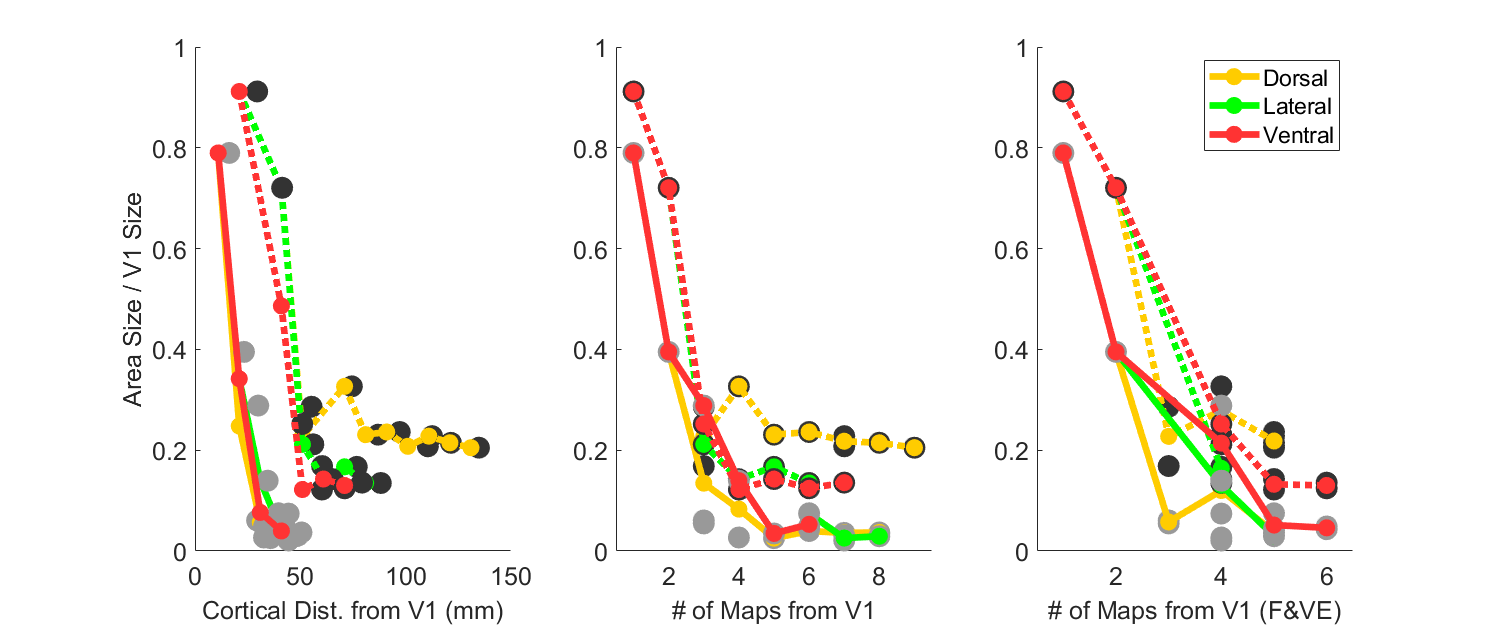

human_all = SA_sumvd_human;
monkey_all = SA_sumvd_monkey;

human_dorsal_idx =  [1, 2, 3, 9, 10, 15:21];
human_lateral_idx = [1, 2, 3, 11:14];
human_ventral_idx = [1, 2, 3, 4:8];

monkey_dorsal_idx =  [1, 2, 3, 4, 5, 11:17];
monkey_lateral_idx = [1, 2, 3, 4, 5, 18:21];
monkey_ventral_idx = [1, 2, 3, 4, 5, 6:10];

human_dorsal = human_all(human_dorsal_idx,:); human_dorsal = human_dorsal./human_dorsal(1,:); human_dorsal = mean(human_dorsal,2,'omitnan');
human_lateral = human_all(human_lateral_idx,:); human_lateral = human_lateral./human_lateral(1,:); human_lateral = mean(human_lateral,2,'omitnan');
human_ventral = human_all(human_ventral_idx,:); human_ventral = human_ventral./human_ventral(1,:); human_ventral = mean(human_ventral,2,'omitnan');
human_allareas = {human_dorsal,human_lateral,human_ventral};
human_areadist = {[human_areadistfromV1(1:3),human_areadistfromV1(human_dorsal_idx(4:end))],...
                  [human_areadistfromV1(1:3),human_areadistfromV1(human_lateral_idx(4:end))],...
                  [human_areadistfromV1(1:3),human_areadistfromV1(human_ventral_idx(4:end))]};
human_hierarchy = {[human_fellemanhierarchy(1:3),human_fellemanhierarchy(human_dorsal_idx(4:end))],...
                  [human_fellemanhierarchy(1:3),human_fellemanhierarchy(human_lateral_idx(4:end))],...
                  [human_fellemanhierarchy(1:3),human_fellemanhierarchy(human_ventral_idx(4:end))]};
human_cortdist = {[meanhumans_cortdist1234(1:3),meanhumans_cortdist1234(human_dorsal_idx(4:end))],...
                  [meanhumans_cortdist1234(1:3),meanhumans_cortdist1234(human_lateral_idx(4:end))],...
                  [meanhumans_cortdist1234(1:3),meanhumans_cortdist1234(human_ventral_idx(4:end))]};

monkey_dorsal = monkey_all(monkey_dorsal_idx,:); monkey_dorsal = monkey_dorsal./monkey_dorsal(1,:); monkey_dorsal = mean(monkey_dorsal,2,'omitnan');
monkey_lateral = monkey_all(monkey_lateral_idx,:); monkey_lateral = monkey_lateral./monkey_lateral(1,:); monkey_lateral = mean(monkey_lateral,2,'omitnan');
monkey_ventral = monkey_all(monkey_ventral_idx,:); monkey_ventral = monkey_ventral./monkey_ventral(1,:); monkey_ventral = mean(monkey_ventral,2,'omitnan');
monks_allareas = {monkey_dorsal,monkey_lateral,monkey_ventral};
monkey_areadist = {[monk_areadistfromV1(1:5),monk_areadistfromV1(monkey_dorsal_idx(6:end))],...
                  [monk_areadistfromV1(1:5),monk_areadistfromV1(monkey_lateral_idx(6:end))],...
                  [monk_areadistfromV1(1:5),monk_areadistfromV1(monkey_ventral_idx(6:end))]};
monkey_hierarchy = {[monk_fellemanhierarchy(1:5),monk_fellemanhierarchy(monkey_dorsal_idx(6:end))],...
                  [monk_fellemanhierarchy(1:5),monk_fellemanhierarchy(monkey_lateral_idx(6:end))],...
                  [monk_fellemanhierarchy(1:5),monk_fellemanhierarchy(monkey_ventral_idx(6:end))]};
monkey_cortdist = {[meanmonks_cortdist1234(1:5),meanmonks_cortdist1234(monkey_dorsal_idx(6:end))],...
                  [meanmonks_cortdist1234(1:5),meanmonks_cortdist1234(monkey_lateral_idx(6:end))],...
                  [meanmonks_cortdist1234(1:5),meanmonks_cortdist1234(monkey_ventral_idx(6:end))]};

% Calculate average correlation with v1 across subjects
human_meanareadist = {};
monk_meanareadist = {};
human_meanhierarchydist = {};
monk_meanhierarchydist = {};
for i = 1:3
    for x = 1:max([monkey_areadist{i},human_areadist{i}])
        human_meanareadist{i}(x)=nanmean(human_allareas{i}(human_areadist{i}==x));
        monk_meanareadist{i}(x)=nanmean(monks_allareas{i}(monkey_areadist{i}==x));
    end
    for x = 1:max([monkey_hierarchy{i},human_hierarchy{i}])
        human_meanhierarchydist{i}(x)=nanmean(human_allareas{i}(human_hierarchy{i}==x)); 
        monk_meanhierarchydist{i}(x)=nanmean(monks_allareas{i}(monkey_hierarchy{i}==x));
    end
end


stepsize=10;
maxrange=150;
human_meancortdist = {};
monk_meancortdist = {};
for i = 1:3
    human_meancortdist{i}=nan(length(1:stepsize:maxrange),1);
    monk_meancortdist{i}=nan(length(1:stepsize:maxrange),1);
    count = 0;
    for x = 1:stepsize:maxrange
        count = count+1;
        if x < 150
            if sum([monkey_cortdist{i}>=x & monkey_cortdist{i}<(x+stepsize)]) > 1
                monk_meancortdist{i}(count)=nanmean(monks_allareas{i}([monkey_cortdist{i}>=x & monkey_cortdist{i}<x+stepsize]));
            elseif sum([monkey_cortdist{i}>=x & monkey_cortdist{i}<(x+stepsize)])
                monk_meancortdist{i}(count)=monks_allareas{i}([monkey_cortdist{i}>=x & monkey_cortdist{i}<(x+stepsize)]);
            end
            if sum([human_cortdist{i}>=x & human_cortdist{i}<(x+stepsize)]) > 1
                human_meancortdist{i}(count)=nanmean(human_allareas{i}([human_cortdist{i}>=x & human_cortdist{i}<(x+stepsize)]));
            elseif sum([human_cortdist{i}>=x & human_cortdist{i}<(x+stepsize)])
                human_meancortdist{i}(count)=human_allareas{i}([human_cortdist{i}>=x & human_cortdist{i}<(x+stepsize)]);
            end
        end
    end
end

%% fix colors
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0];
lateralcolor=[0.2784    0.5216    0.1451];
human_colors = [dorsalcolor;lateralcolor;ventralcolor];

ventralcolor=[1 0.2 0.2];
dorsalcolor=[1 .8 0];
lateralcolor=[0 1 0];
monkey_colors = [dorsalcolor;lateralcolor;ventralcolor];

xvals = 1:stepsize:maxrange;

figure('Renderer', 'painters', 'Position', [10 10 1200 500])
subplot(1,3,1) 
hold on
for i = 1:3
    plot(human_cortdist{i}(2:end),human_allareas{i}(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
    plot(monkey_cortdist{i}(2:end),monks_allareas{i}(2:end),'.','color',[.6 .6 .6],'MarkerSize',45)
    omitnan = find(~isnan(human_meancortdist{i}));
    plot(xvals(omitnan),human_meancortdist{i}(omitnan),'.:','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
    plot(xvals,monk_meancortdist{i},'.-','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
end
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
% xlim([0.5 max([meanmonks_cortdist1234,meanhumans_cortdist1234])+.5])
xlabel('Cortical Dist. from V1 (mm)','fontsize',15)
ylabel('Area Size / V1 Size','fontsize',15)

subplot(1,3,2)
hold on
for i = 1:3
plot(human_areadist{i}(2:end),human_allareas{i}(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(monkey_areadist{i}(2:end),monks_allareas{i}(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(human_meanareadist{i},'.:','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
plot(monk_meanareadist{i},'.-','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
end
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([monk_areadistfromV1,human_areadistfromV1])+.5])
xlabel('# of Maps from V1','Fontsize',15)
 
subplot(1,3,3)
hold on
for i = 1:3
plot(human_hierarchy{i}(2:end),human_allareas{i}(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(monkey_hierarchy{i}(2:end),monks_allareas{i}(2:end),'.','color',[.6 .6 .6],'MarkerSize',45)
xval = 1:length(human_meanhierarchydist{i});
omitnan = find(~isnan(human_meanhierarchydist{i}));
plot(xval(omitnan),human_meanhierarchydist{i}(omitnan),'.:','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
xval = 1:length(monk_meanhierarchydist{i});
omitnan = find(~isnan(monk_meanhierarchydist{i}));
plot(xval(omitnan),monk_meanhierarchydist{i}(omitnan),'.-','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
end
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([monk_fellemanhierarchy,human_fellemanhierarchy])+.5])
xlabel('# of Maps from V1 (F&VE)','Fontsize',15)
legend('','','','Dorsal','','','','Lateral','','','','Ventral')

neo_size = load('Humans/NeonatalComparison/allvisualareadata.mat');
neo_dist = load('Humans/AreaDistances_neonate.mat');

surfacearea_smoothwm{1} = neo_size.allsubjs_smoothwm_rh([2:14,16:end],:);surfacearea_smoothwm{2} = neo_size.allsubjs_smoothwm_lh([2:14,16:end],:);
surfacearea_pial{1} = neo_size.allsubjs_pial_rh([2:14,16:end],:);surfacearea_pial{2} = neo_size.allsubjs_pial_lh([2:14,16:end],:);

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
neo_surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

neo_bothhemi_SA = [neo_surfacearea_avg{1}, neo_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(neo_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(neo_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(neo_bothhemi_SA(5:6,:),1);

SA_sumvd_neo = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;neo_bothhemi_SA(7:end,:)];


% Neonate Data
disp(neo_dist.area_labels)

  Columns 1 through 13

    {'V1all'}    {'V1v'}    {'V1d'}    {'V2v'}    {'V2d'}    {'V3v'}    {'V3d'}    {'V3A'}    {'V3B'}    {'LO1'}    {'LO2'}    {'TO1'}    {'TO2'}

  Columns 14 through 25

    {'hV4'}    {'VO1'}    {'VO2'}    {'PHC1'}    {'PHC2'}    {'IPS0'}    {'IPS1'}    {'IPS2'}    {'IPS3'}    {'IPS4'}    {'IPS5'}    {'SPL1'}

  Columns 26 through 27

    {'FEF'}    {'IFS'}



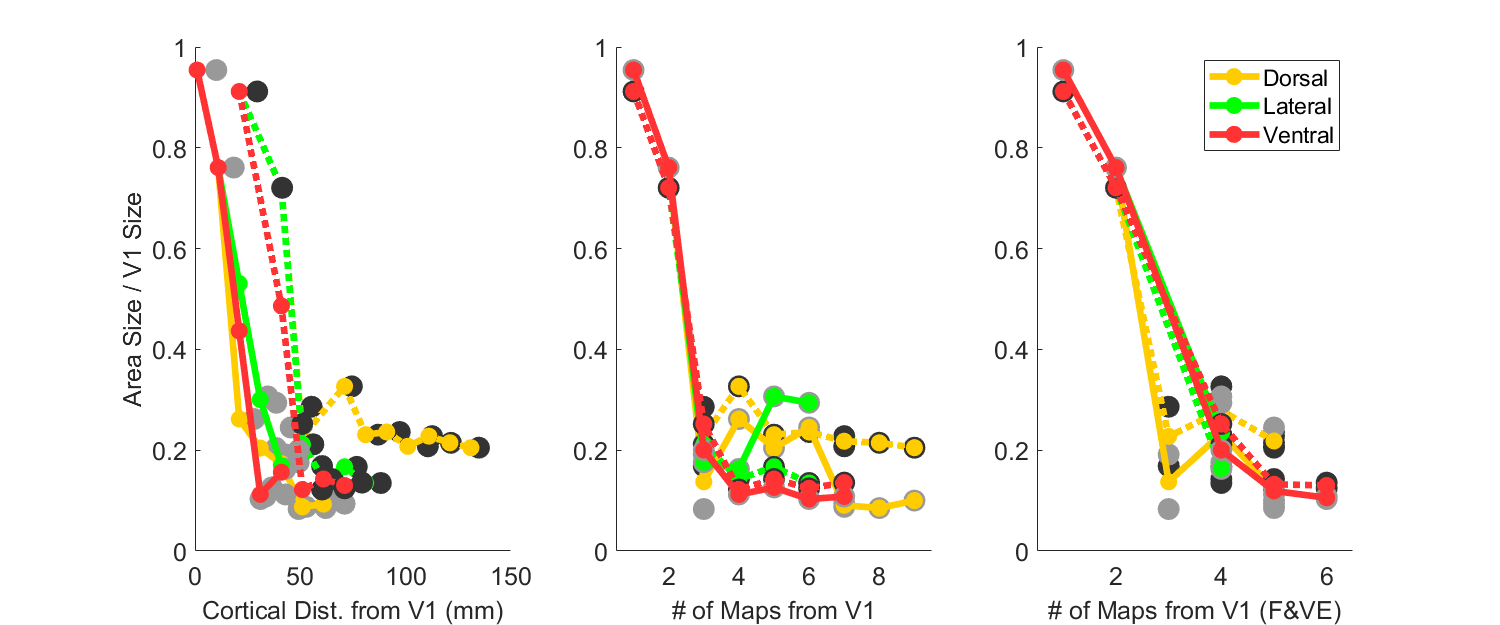

dist_to_data_idx = [2,3,4,5,6,7,14,15,16,17,18,8,9,10,11,12,13,19,20,21,22,23,24,25];
from_v1_idx = find(neo_dist.alluniqueroinodepairs(:,1)==0);
distance_from_v1_rh = neo_dist.allareadistancesavglayer_rh(from_v1_idx,:);
distance_from_v1_lh = neo_dist.allareadistancesavglayer_lh(from_v1_idx,:);
dist_from_v1_rh = distance_from_v1_rh(dist_to_data_idx-1,:);
dist_from_v1_lh = distance_from_v1_lh(dist_to_data_idx-1,:);
neo_labels_vd = neo_dist.area_labels(dist_to_data_idx);

meanneo_cortdist_rh = mean(dist_from_v1_rh,2,'omitnan');
meanneo_cortdist_lh = mean(dist_from_v1_lh,2,'omitnan');

meanneo_cortdist_rh1234=[];
meanneo_cortdist_rh1234(1)=0;
meanneo_cortdist_rh1234(2)=[meanneo_cortdist_rh(3)+meanneo_cortdist_rh(4)]/2;
meanneo_cortdist_rh1234(3)=[meanneo_cortdist_rh(5)+meanneo_cortdist_rh(6)]/2;
meanneo_cortdist_rh1234=[meanneo_cortdist_rh1234,meanneo_cortdist_rh(7:end)'];

meanneo_cortdist_lh1234=[];
meanneo_cortdist_lh1234(1)=0;
meanneo_cortdist_lh1234(2)=[meanneo_cortdist_lh(3)+meanneo_cortdist_lh(4)]/2;
meanneo_cortdist_lh1234(3)=[meanneo_cortdist_lh(5)+meanneo_cortdist_lh(6)]/2;
meanneo_cortdist_lh1234=[meanneo_cortdist_lh1234,meanneo_cortdist_lh(7:end)'];

meanneo_cortdist1234=[meanneo_cortdist_rh1234+meanneo_cortdist_lh1234]/2;

%%
human_all = SA_sumvd_human;
neo_all = SA_sumvd_neo;

human_dorsal_idx =  [1, 2, 3, 9, 10, 15:21];
human_lateral_idx = [1, 2, 3, 11:14];
human_ventral_idx = [1, 2, 3, 4:8];

human_dorsal = human_all(human_dorsal_idx,:); human_dorsal = human_dorsal./human_dorsal(1,:); human_dorsal = mean(human_dorsal,2,'omitnan');
human_lateral = human_all(human_lateral_idx,:); human_lateral = human_lateral./human_lateral(1,:); human_lateral = mean(human_lateral,2,'omitnan');
human_ventral = human_all(human_ventral_idx,:); human_ventral = human_ventral./human_ventral(1,:); human_ventral = mean(human_ventral,2,'omitnan');
human_allareas = {human_dorsal,human_lateral,human_ventral};
human_areadist = {[human_areadistfromV1(1:3),human_areadistfromV1(human_dorsal_idx(4:end))],...
                  [human_areadistfromV1(1:3),human_areadistfromV1(human_lateral_idx(4:end))],...
                  [human_areadistfromV1(1:3),human_areadistfromV1(human_ventral_idx(4:end))]};
human_hierarchy = {[human_fellemanhierarchy(1:3),human_fellemanhierarchy(human_dorsal_idx(4:end))],...
                  [human_fellemanhierarchy(1:3),human_fellemanhierarchy(human_lateral_idx(4:end))],...
                  [human_fellemanhierarchy(1:3),human_fellemanhierarchy(human_ventral_idx(4:end))]};
human_cortdist = {[meanhumans_cortdist1234(1:3),meanhumans_cortdist1234(human_dorsal_idx(4:end))],...
                  [meanhumans_cortdist1234(1:3),meanhumans_cortdist1234(human_lateral_idx(4:end))],...
                  [meanhumans_cortdist1234(1:3),meanhumans_cortdist1234(human_ventral_idx(4:end))]};

neo_dorsal = neo_all(human_dorsal_idx,:); neo_dorsal = neo_dorsal./neo_dorsal(1,:); neo_dorsal = mean(neo_dorsal,2,'omitnan');
neo_lateral = neo_all(human_lateral_idx,:); neo_lateral = neo_lateral./neo_lateral(1,:); neo_lateral = mean(neo_lateral,2,'omitnan');
neo_ventral = neo_all(human_ventral_idx,:); neo_ventral = neo_ventral./neo_ventral(1,:); neo_ventral = mean(neo_ventral,2,'omitnan');
neo_allareas = {neo_dorsal,neo_lateral,neo_ventral};
neo_areadist = {[human_areadistfromV1(1:3),human_areadistfromV1(human_dorsal_idx(4:end))],...
                  [human_areadistfromV1(1:3),human_areadistfromV1(human_lateral_idx(4:end))],...
                  [human_areadistfromV1(1:3),human_areadistfromV1(human_ventral_idx(4:end))]};
neo_hierarchy = {[human_fellemanhierarchy(1:3),human_fellemanhierarchy(human_dorsal_idx(4:end))],...
                  [human_fellemanhierarchy(1:3),human_fellemanhierarchy(human_lateral_idx(4:end))],...
                  [human_fellemanhierarchy(1:3),human_fellemanhierarchy(human_ventral_idx(4:end))]};
neo_cortdist = {[meanneo_cortdist1234(1:5),meanneo_cortdist1234(human_dorsal_idx(6:end))],...
                  [meanneo_cortdist1234(1:5),meanneo_cortdist1234(human_lateral_idx(6:end))],...
                  [meanneo_cortdist1234(1:5),meanneo_cortdist1234(human_ventral_idx(6:end))]};

% Calculate average correlation with v1 across subjects
neo_meanareadist = {};
neo_meanhierarchydist = {};
for i = 1:3
    for x = 1:max(neo_areadist{i})
        neo_meanareadist{i}(x)=nanmean(neo_allareas{i}(neo_areadist{i}==x));
    end
    for x = 1:max(neo_hierarchy{i})
        neo_meanhierarchydist{i}(x)=nanmean(neo_allareas{i}(neo_hierarchy{i}==x));
    end
end

stepsize=10;
maxrange=150;
neo_meancortdist = {};
for i = 1:3
    neo_meancortdist{i}=nan(length(1:stepsize:maxrange),1);
    count = 0;
    for x = 1:stepsize:maxrange
        count = count+1;
        if x < 150
            if sum([neo_cortdist{i}>=x & neo_cortdist{i}<(x+stepsize)]) > 1
                neo_meancortdist{i}(count)=nanmean(neo_allareas{i}([neo_cortdist{i}>=x & neo_cortdist{i}<x+stepsize]));
            elseif sum([neo_cortdist{i}>=x & neo_cortdist{i}<(x+stepsize)])
                neo_meancortdist{i}(count)=neo_allareas{i}([neo_cortdist{i}>=x & neo_cortdist{i}<(x+stepsize)]);
            end
        end
    end
    if i==2 || i==3
        neo_meancortdist{i}(3)=[neo_meancortdist{i}(2)+neo_meancortdist{i}(4)]/2;
    end
end
% neo_meancortdist(4)=[neo_meancortdist(3)+neo_meancortdist(5)]/2;
% human_meancortdist(7)=[human_meancortdist(6)+human_meancortdist(8)]/2;
% human_meancortdist(14)=[human_meancortdist(13)+human_meancortdist(15)]/2;


%% fix colors
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0];
lateralcolor=[0.2784    0.5216    0.1451];
human_colors = [dorsalcolor;lateralcolor;ventralcolor];

ventralcolor=[1 0.2 0.2];
dorsalcolor=[1 .8 0];
lateralcolor=[0 1 0];
monkey_colors = [dorsalcolor;lateralcolor;ventralcolor];

xvals = 1:stepsize:maxrange;

figure('Renderer', 'painters', 'Position', [10 10 1200 500])
subplot(1,3,1) 
hold on
for i = 1:3
    plot(human_cortdist{i}(2:end),human_allareas{i}(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
    plot(neo_cortdist{i}(2:end),neo_allareas{i}(2:end),'.','color',[.6 .6 .6],'MarkerSize',45)
    omitnan = find(~isnan(human_meancortdist{i}));
    plot(xvals(omitnan),human_meancortdist{i}(omitnan),'.:','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
    plot(xvals,neo_meancortdist{i},'.-','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
end
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
% xlim([0.5 max([meanmonks_cortdist1234,meanhumans_cortdist1234])+.5])
xlabel('Cortical Dist. from V1 (mm)','fontsize',15)
ylabel('Area Size / V1 Size','fontsize',15)

subplot(1,3,2)
hold on
for i = 1:3
plot(human_areadist{i}(2:end),human_allareas{i}(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(neo_areadist{i}(2:end),neo_allareas{i}(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(human_meanareadist{i},'.:','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
plot(neo_meanareadist{i},'.-','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
end
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([human_areadistfromV1])+.5])
xlabel('# of Maps from V1','Fontsize',15)
 
subplot(1,3,3)
hold on
for i = 1:3
plot(human_hierarchy{i}(2:end),human_allareas{i}(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(neo_hierarchy{i}(2:end),neo_allareas{i}(2:end),'.','color',[.6 .6 .6],'MarkerSize',45)
xval = 1:length(human_meanhierarchydist{i});
omitnan = find(~isnan(human_meanhierarchydist{i}));
plot(xval(omitnan),human_meanhierarchydist{i}(omitnan),'.:','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
xval = 1:length(neo_meanhierarchydist{i});
omitnan = find(~isnan(neo_meanhierarchydist{i}));
plot(xval(omitnan),neo_meanhierarchydist{i}(omitnan),'.-','MarkerSize',35,'LineWidth',4,'Color',monkey_colors(i,:))
end
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([human_fellemanhierarchy])+.5])
xlabel('# of Maps from V1 (F&VE)','Fontsize',15)
legend('','','','Dorsal','','','','Lateral','','','','Ventral')